hole = readtable("lab7/deathstar/hole.csv");
north = readtable("lab7/deathstar/hemi 1.csv");
south = readtable("lab7/deathstar/hemi 2.csv");

table_type = getEmptyTable();
home = table_type;
home(1,:) = {0.127,0.127, true, 0, 0};


hole =removeborder(hole);
north =removeborder(north);
south =removeborder(south);


% start from a better position instead of from the top
north_start = 114;
north = [
    north(north_start:end,:)  ;
    north(1:north_start,:)  
];



% initial and final position must be the same
hole =closure(hole);
north =closure(north);
south =closure(south);


% SVG coordinates are negative of the CARTESIAN

hole.y = 1044-hole.y;
north.y = 1044-north.y;
south.y = 1044-south.y;

% 20px of border
hole.x = hole.x-20;
north.x = north.x-20;
south.x = south.x-20;

% center it
hole = hole -1024/2;
north = north -1024/2;
south = south -1024/2;

% scale to fit into 8cm
scal = 4/50000;
hole = hole.*scal;
north = north.*scal;
south = south.*scal;

% center at [13 13.5]

hole = hole + [0.13 0.135];
north = north + [0.13 0.135];
south = south + [0.13 0.135];


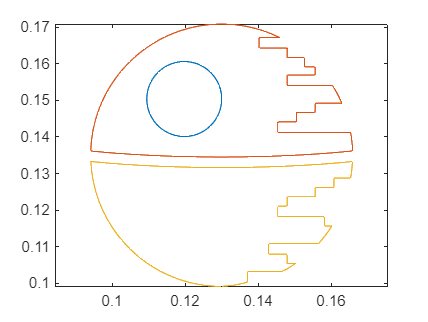


figure
plot(hole.x,hole.y)
hold on
plot(north.x,north.y)
plot(south.x,south.y)
axis equal
hold off

## assemble figure

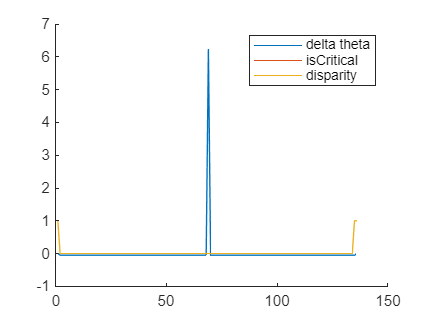


hole = waitAtCorners(hole);

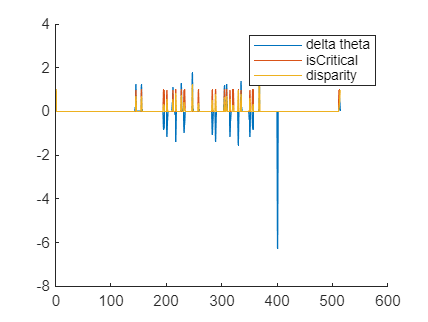

north = waitAtCorners(north);

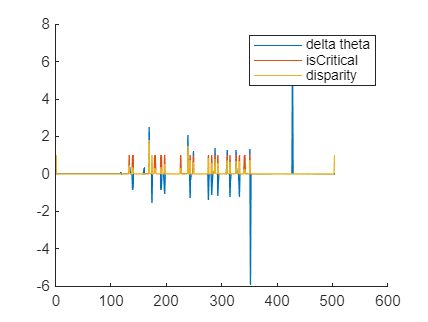

south = waitAtCorners(south);

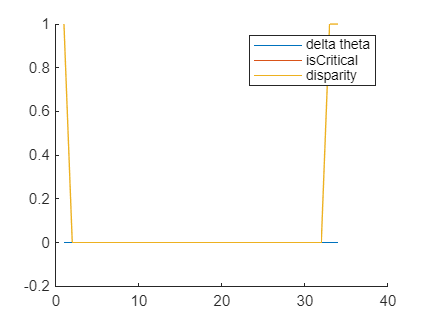



traj_mat = JoinPaths(home,north,1e-3);

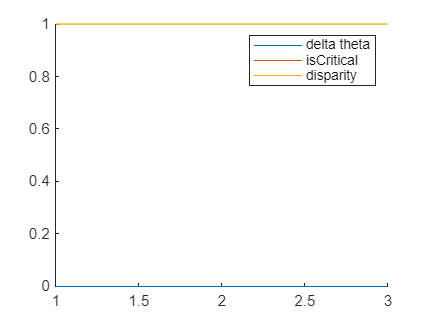

traj_mat = JoinPaths(traj_mat,south,1e-3);

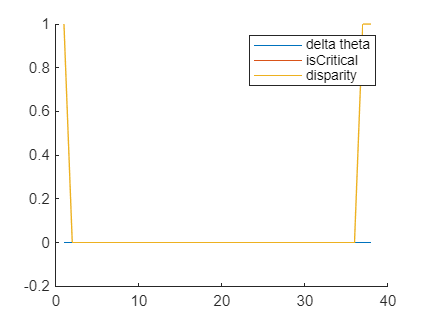

traj_mat = JoinPaths(traj_mat,hole,1e-3);

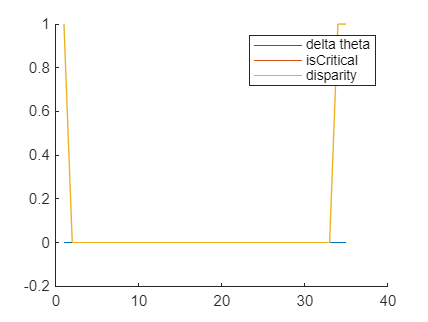

traj_mat = JoinPaths(traj_mat,home,1e-3);

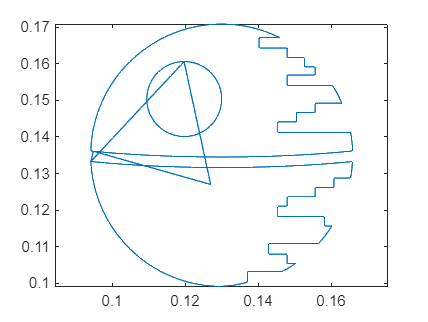



x = traj_mat.x;
y = traj_mat.y;

time_total = 30;
steps = size(traj_mat,1);
t = linspace(0,time_total,steps)';

traj = table(t,x,y); 



plot(traj.x,traj.y)
axis equal

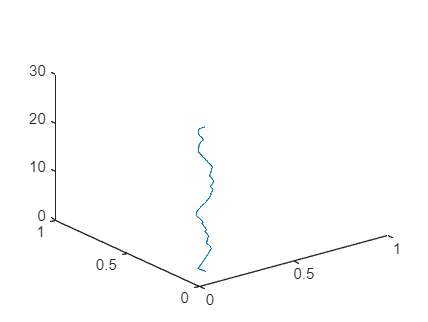

figure
plot3(traj.x,traj.y,traj.t)
axis 'auto z'

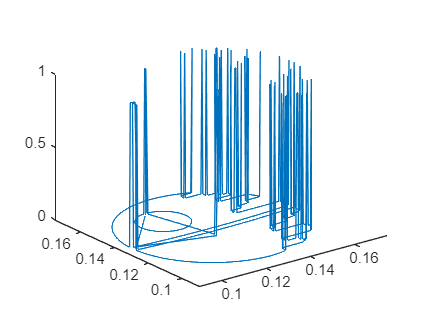


figure
plot3(traj_mat.x,traj_mat.y,traj_mat.critical)
axis 'auto z'
ylim([0.13-0.04 0.135+0.04])
xlim([0.13-0.04 0.135+0.04])



traj_ts = timeseries(traj_mat,t,"Name","DeathStar");

function [filtered] = removeborder(tab)
% filtered = [20,20];
% start = {20 , 20};
% finish = {1044 , 1044};
% filtered = [start];
    filtered = [];
    for i = 1:size(tab,1)
        
        if tab.y(i)>21 && tab.y(i)<1043 && tab.x(i)>21 && tab.x(i)<1043
        filtered = [
            filtered;
            tab(i,:)
        ];
        end   
    
    end

% filtered = [
%         filtered;
%        finish
%     ];
end



function [newPath] = JoinPaths(previous, next, delta )
    dwell_n = 1;
    dx = next.x(1)- previous.x(end);
    dy = next.y(1)- previous.y(end);
    
    dist = sqrt(dx^2 +dy^2);
    
    n_steps = ceil(dist/delta);
    
    x = linspace(previous.x(end),next.x(1),n_steps)';
    y = linspace(previous.y(end),next.y(1),n_steps)';
    
    


    seq = table(x,y);

    seq  = waitAtCorners(seq);
    dwell_start = [];
    dwell_stop = [];
    
    for i=1:dwell_n
        dwell_start = [dwell_start; previous(end,:)];
    
        dwell_stop = [dwell_stop; next(1,:)];
    
    end
    newPath = [
        previous;
        dwell_start;
        seq;
        dwell_stop;
        next];
end


function [closed] = closure(path)
    closed = [path;
        path(1,:)
    ];

end


function [e_path] = waitAtCorners(path)
    n_dwell = 1;
    dx = path.x(2:end)-path.x(1:end-1);
    dy = path.y(2:end)-path.y(1:end-1);

    % angle change as correlation
    


    % norm = sqrt(dx.^2 + dy.^2);
    
    theta = atan2(dy,dx);
    
    delta_theta = theta(2:end)-theta(1:end-1);
    delta_theta = [0; delta_theta; 0]; % padding
    isC = zeros(3,size(path,1));





        
    isC(1,:) = delta_theta;

    dx_pad = [0; dx; 0];
    dy_pad = [0; dy; 0];
    
    threshold = cos(30);
    temp = getEmptyTable();
    e_path = [];
    for i = 1:size(path,1)

        if  i > 1 && i < size(path,1)-1
            angle_disparity_num = dx(i-1)*dx(i) +  dy(i-1)*dy(i) ;
            angle_disparity_den = sqrt(dx(i-1)^2 + dy(i-1)^2)*sqrt(dx(i)^2+dy(i)^2);
            angle_disparity = 1- angle_disparity_num/angle_disparity_den;
        else
            angle_disparity = 1;
        end


        if (angle_disparity>threshold) 
            isCritical = true;
        else
            isCritical = false;
        end
        isC(3,i) = angle_disparity;
        isC(2,i) = isCritical;

        temp(1,:) = { path.x(i),  path.y(i),  isCritical, dx_pad(i),  dy_pad(i), };

        e_path = [e_path ; temp];

    end

    figure
    hold on    
plot(delta_theta)
plot(isC(2,:))
plot(isC(3,:))
hold off

legend("delta theta","isCritical","disparity")
end


function [tab] = getEmptyTable()

tab = table('Size',[1 5], ...
    'VariableTypes',["double","double","logical","double","double"], ...
    'VariableNames',[ "x", "y" , "critical", "vx" ,"vy" ]);
end